# データを図示してモデルを選択する

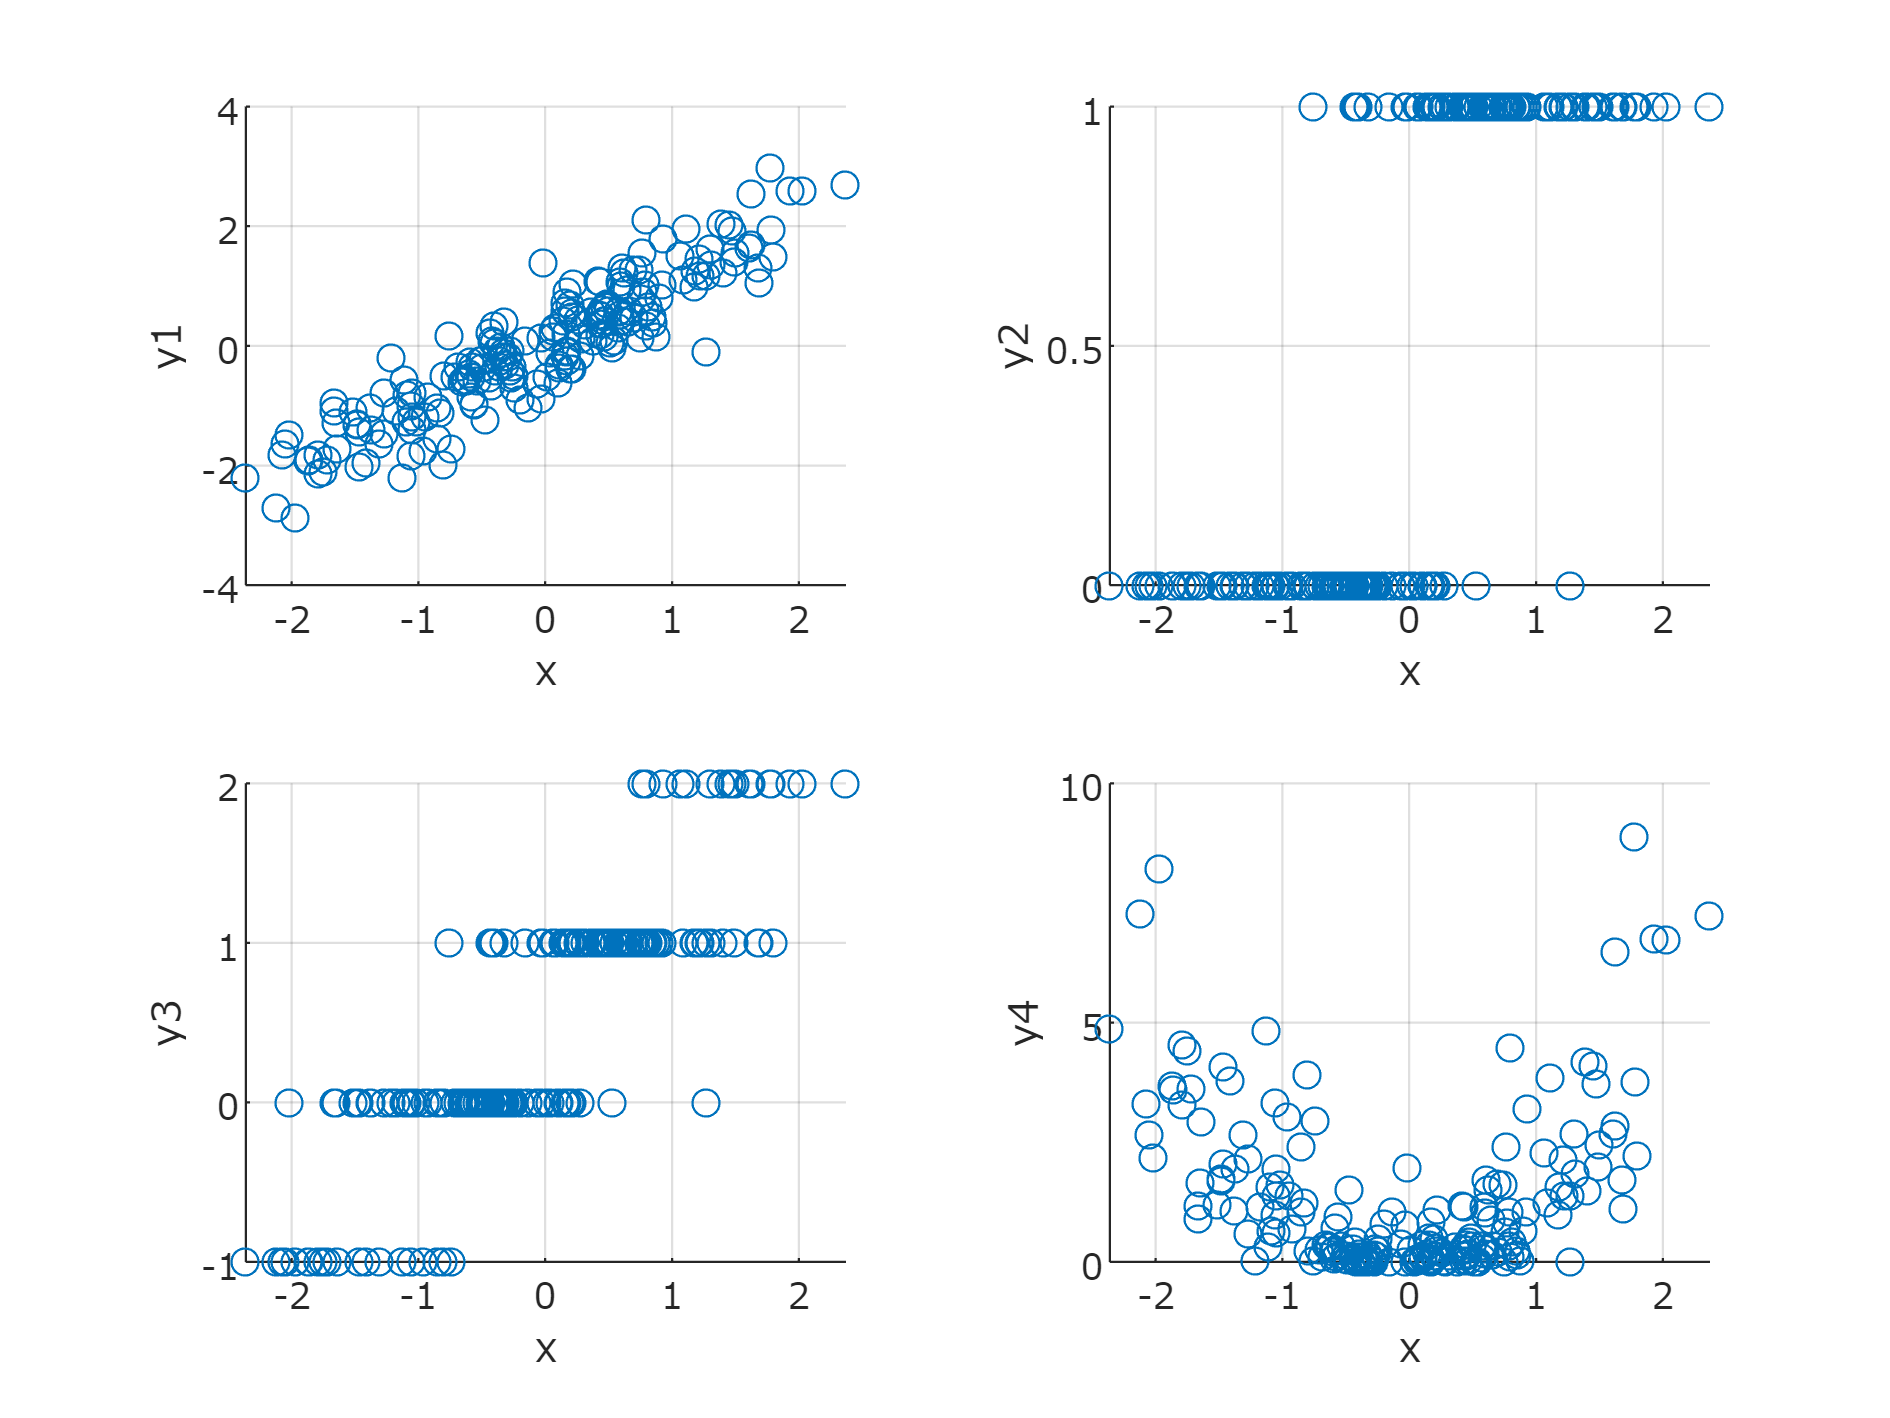

clear;clc;close all;

tbl=readtable('../data/data_ExerciseChap4.csv');

figure;
tiledlayout(2,2);
nexttile;
scatter(tbl.x, tbl.y1);
set(gca,'fontname','メイリオ');grid on;
xlabel('x');ylabel('y1');

nexttile;
scatter(tbl.x, tbl.y2);
set(gca,'fontname','メイリオ');grid on;
xlabel('x');ylabel('y2');

nexttile;
scatter(tbl.x, tbl.y3);
set(gca,'fontname','メイリオ');grid on;
xlabel('x');ylabel('y3');

nexttile;
scatter(tbl.x, tbl.y4);
set(gca,'fontname','メイリオ');grid on;
xlabel('x');ylabel('y4');

exportgraphics(gcf,'fig_EDA_ExerciseChap4.pdf');

mdl1=glmfit(tbl.x, tbl.y1);
mdl2=glmfit(tbl.x,tbl.y2,"binomial");

y3Vals=unique(tbl.y3);
mdl3=[];
for y3Val=y3Vals'
    tmpMdl=glmfit(tbl.x, tbl.y3<=y3Val,'binomial');
    mdl3=[mdl3 tmpMdl];
end

mdl4=stepwiseglm(tbl.x,tbl.y4,"quadratic")

初期モデルに追加する、または初期モデルから削除する項はありません。


mdl4 = 一般化線形回帰モデル:
    y ~ 1 + x1 + x1^2
     分布は Normal です

推定された係数: 
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     0.1889     0.096635    1.9548       0.05202
    x1             0.18679     0.076401    2.4449      0.015369
    x1^2            1.1389     0.063715    17.874    4.2295e-43


200 の観測値、197 の誤差の自由度
推定される分散:  1.11
F 統計量 - 定数モデルとの比較: 160、p 値は 5.73e-42 です

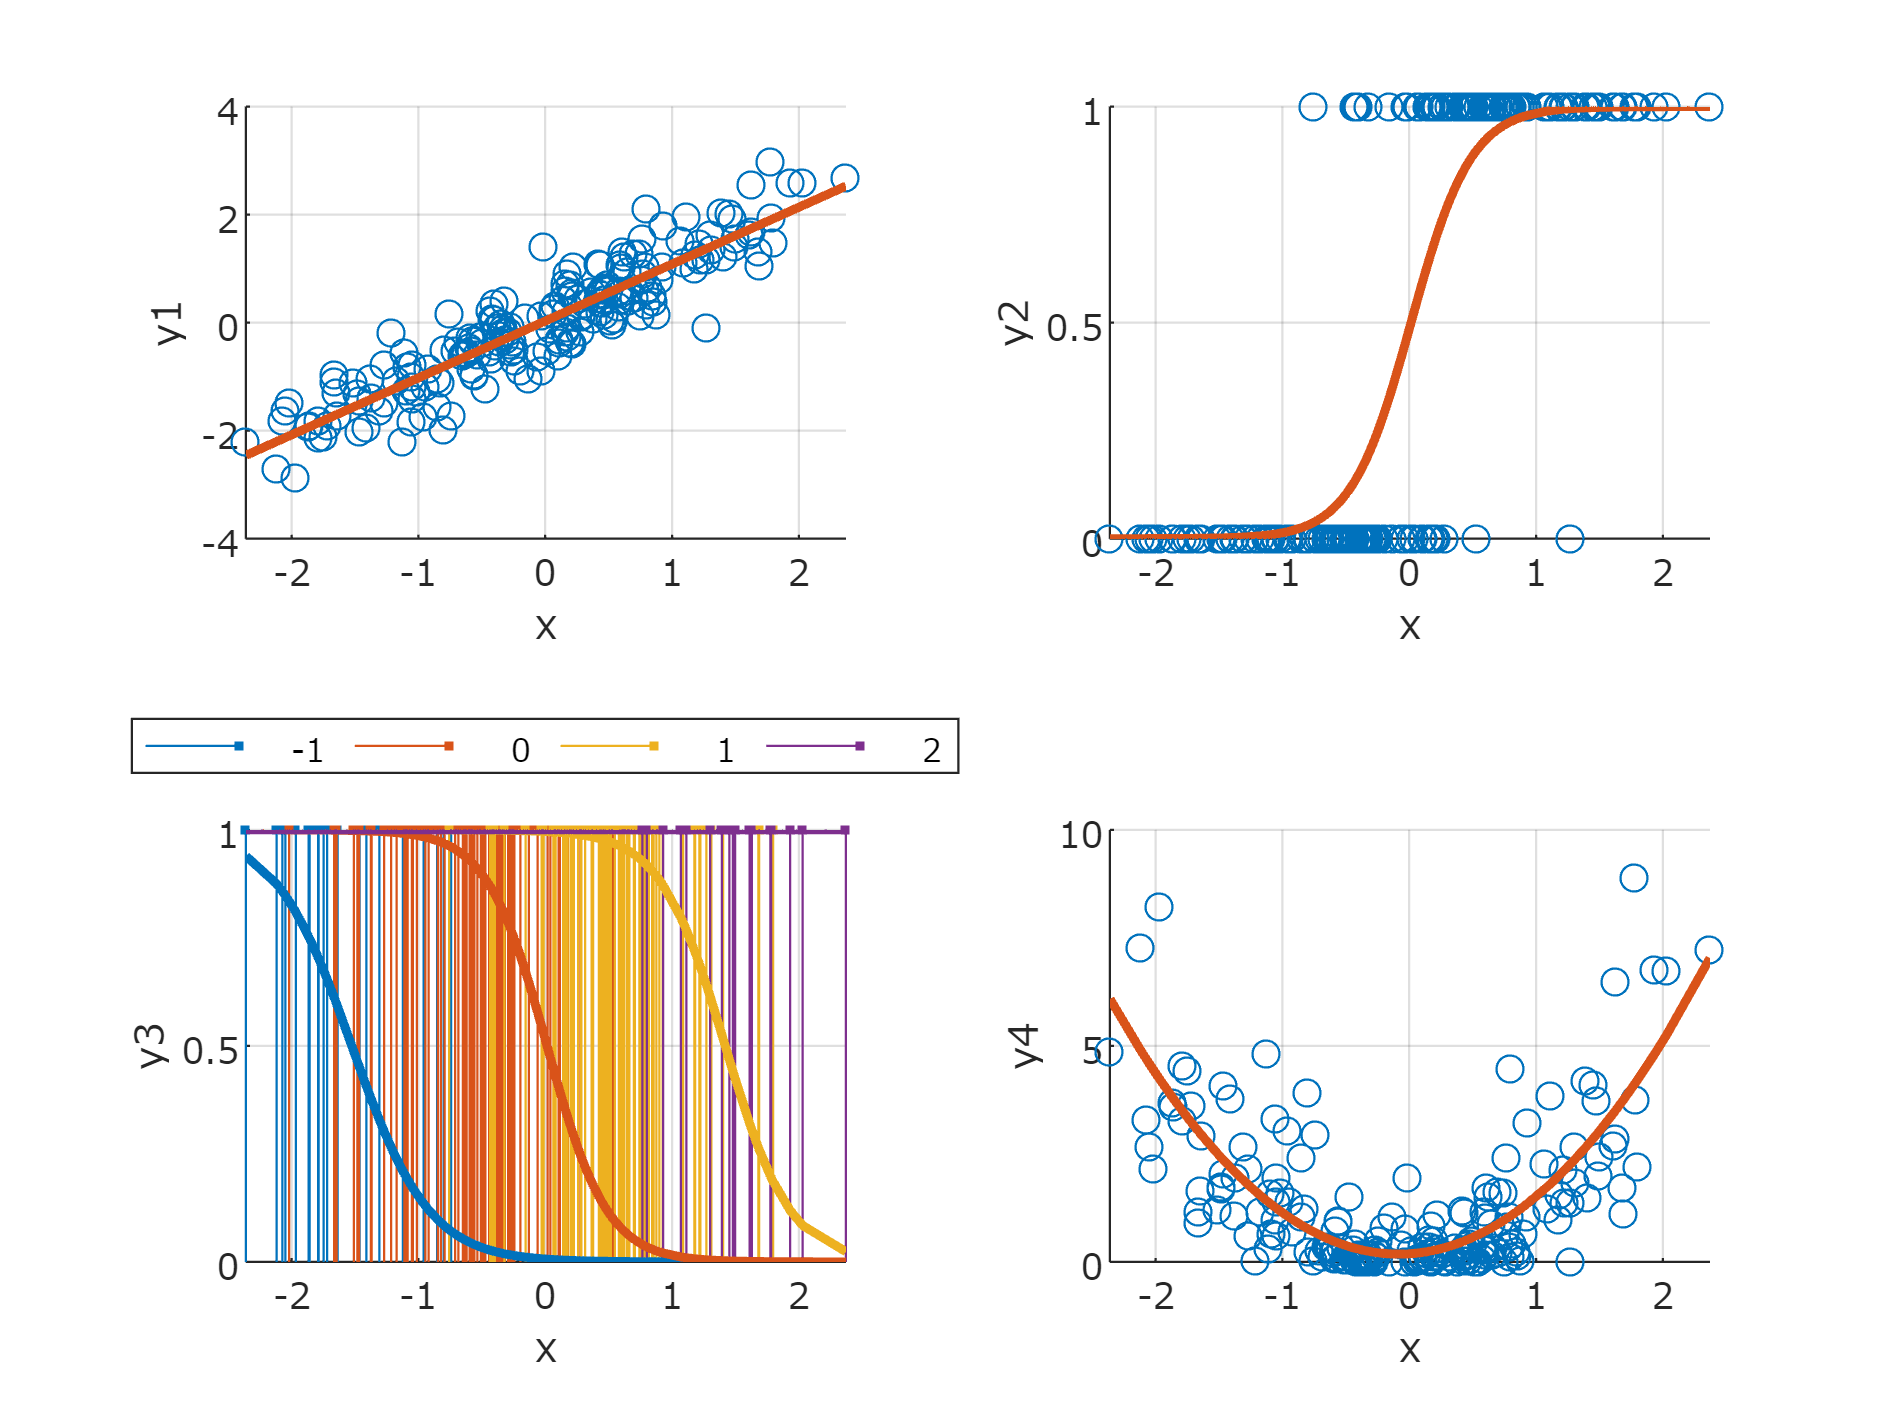


figure;
tiledlayout(2,2);
nexttile;
scatter(tbl.x, tbl.y1);
set(gca,'fontname','メイリオ');grid on;hold on;
plot(sort(tbl.x), glmval(mdl1, sort(tbl.x), "identity"), ...
    'LineWidth',2);
xlabel('x');ylabel('y1');

nexttile;
scatter(tbl.x, tbl.y2);
set(gca,'fontname','メイリオ');grid on;hold on;
plot(sort(tbl.x), glmval(mdl2, sort(tbl.x), "logit"), ...
    'LineWidth',2);
xlabel('x');ylabel('y2');

nexttile;
set(gca,'fontname','メイリオ');grid on;hold on;
for y3Val=y3Vals'
    ind = tbl.y3==y3Val;
    stem(tbl.x(ind),ones(sum(ind),1),'.-');
end
set(gca,'colororderindex',1);
for n1=1:size(mdl3,2)
    plot(sort(tbl.x), glmval(mdl3(:,n1), sort(tbl.x), 'logit'),'LineWidth',2);
end
xlabel('x');ylabel('y3');
legend(num2str(y3Vals),'Location','northoutside','Orientation','horizontal')

nexttile;
scatter(tbl.x, tbl.y4);
set(gca,'fontname','メイリオ');grid on;hold on;
plot(sort(tbl.x), predict(mdl4, sort(tbl.x)), ...
    'LineWidth',2);

xlabel('x');ylabel('y4');
exportgraphics(gcf,'fig_EDA_ExerciseChap4_ans.pdf');